# Title & Project Overview

% This Live Script documents the complete thermal design process for a radiator to cool the motor and motor controllers.
% The radiator must reject a peak heat load of 5.5 kW under worst-case operating conditions (defined as maximum motor load at low vehicle speed, where ram air contribution is negligible and cooling is provided by an electric fan only)

## Fixed Inputs & Constants

clear; clc; close all;
% operating conditions 
Q_target = 5500; %(W)
T_coolant_in = 60; %(°C)
T_air_in = 25; %ambient air temp of 25 assumed (°C)
v_air = 1.5; %ram air assumed 0 for worst conditions, face velocity assumed to be 1.5m/s

% fixed geometry (all in m)
d = 0.032; % common values added as options for depth of radiator 
H = 0.35; % range of 30-40cm added for height with steps of 25mm
a_tube = 0.002; % dimensions of rectangular tube, height as 2mm
b_tube = d; % width of tube taken equal to depth of radiator 
tube_pitch = 0.010; % height of tube(2mm) + fin space(8mm), used to calculate number of tubes 
D_h = (4*a_tube*b_tube)/(2*(a_tube+b_tube)); % hydraulic diameter of tube
A_tube = a_tube*b_tube; % tube cross sectional area (m²)

% air properties at 25°C
rho_air = 1.225; %density (kg/m³)
mu_air = 0.0000186; %viscosity (kg/m*s)
k_air = 0.026; %thermal conductivity (W/m*K)
cp_air = 1005; %specific heat capacity (J/kg*K)
Pr_air = 0.71; %Prandtl number (dimensionless)

% water properties at 57°C (avg of 60°C and 53°C (approx t_coolant_out))
rho_water = 984.7;
mu_water = 0.000489;
k_water = 0.651; 
cp_water = 4183;  
Pr_water = 3.14;

% parameter ranges 
sigma_range = linspace(500, 3000, 100); %fin area density (m²/m³)
A_face_range = linspace(0.05, 0.40, 100); %radiator face area (m²)


## Heat Transfer Calculations

Q_predicted = zeros(length(A_face_range), length(sigma_range)); %results matrix 
W_calculated = zeros(length(A_face_range), length(sigma_range)); %width matrix 

%air side convection heat transfer coefficient 
Re_air = (rho_air*v_air*d)/mu_air;
Nu_air = 0.664*(Re_air^0.5)*(Pr_air^(1/3));
h_air = (Nu_air*k_air)/d;

%water side convection heat transfer coefficient
mdot_coolant = 0.2; %CHANGE HERE (rn 12L/min or 200g/s)
n_tubes = floor(H/tube_pitch); %number of tubes 
mdot_tube = mdot_coolant/n_tubes; %mass flow rate per tube 
v_water = mdot_tube/(rho_water*A_tube); %velocity of water in each tube
Re_water = (rho_water*v_water*D_h)/mu_water;
Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.4);
h_water = (Nu_water*k_water)/D_h;

U = 1/((1/h_air)+(1/h_water)); %overall heat transfer coefficient 

for i = 1:length(A_face_range)
    for j = 1:length(sigma_range)

        A_face = A_face_range(i);
        sigma = sigma_range(j);

        W_calculated(i,j) = A_face/H; %width stored for plotting

        %capacity rates 
        C_air = rho_air*v_air*cp_air*A_face;
        C_water = mdot_coolant*cp_water;
        C_min = min(C_air,C_water);
        C_max = max(C_air,C_water);
        C_star = C_min/C_max;

        A_fins = sigma*A_face*d; %total surface area in contact 
        NTU = (U*A_fins)/C_min; %number of transfer units 
        epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1)); 

        Q_predicted(i,j) = epsilon*C_min*(T_coolant_in-T_air_in);
    end
end


## Plotting Heat Rejected with Area and Fin Density

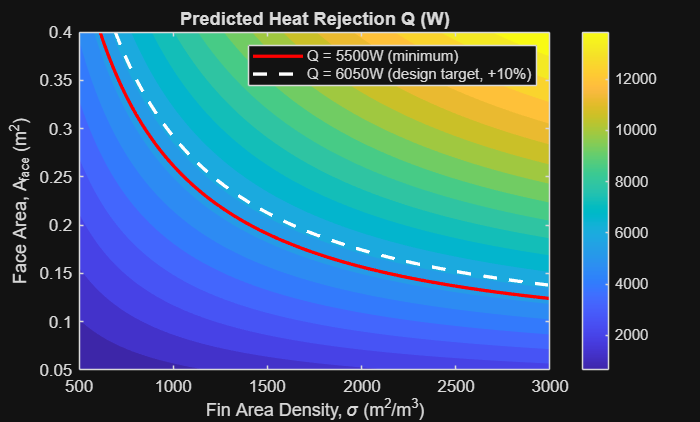

figure;
contourf(sigma_range, A_face_range, Q_predicted, 20, 'LineColor', 'none');
colorbar;
xlabel('Fin Area Density, \sigma (m^2/m^3)');
ylabel('Face Area, A_{face} (m^2)');
title('Predicted Heat Rejection Q (W)');
hold on;

% Critical boundary - minimum requirement
contour(sigma_range, A_face_range, Q_predicted, [5500 5500], 'r', 'LineWidth', 2);

% Adding a safety factor of 1.1 (considering all the worst case conditions
% assumed)
contour(sigma_range, A_face_range, Q_predicted, [6050 6050], 'w--', 'LineWidth', 2);

legend('', 'Q = 5500W (minimum)', 'Q = 6050W (design target, +10%)');
hold off;

## Plot Width of Radiator

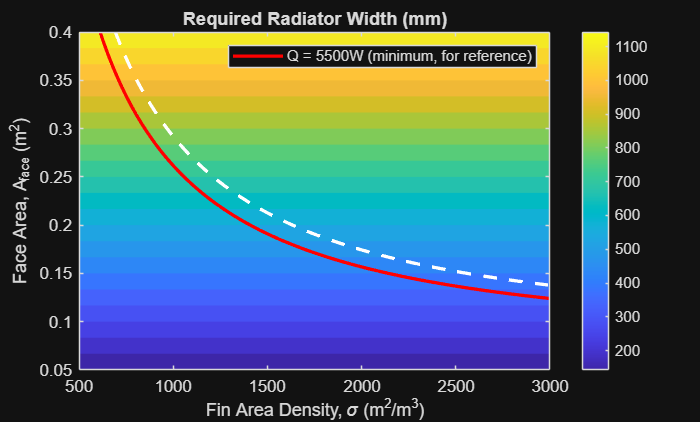

figure;
contourf(sigma_range, A_face_range, W_calculated*1000, 20, 'LineColor', 'none');
c = colorbar;
clim([min(W_calculated(:))*1000, max(W_calculated(:))*1000]);
xlabel('Fin Area Density, \sigma (m^2/m^3)');
ylabel('Face Area, A_{face} (m^2)');
title('Required Radiator Width (mm)');
hold on;
contour(sigma_range, A_face_range, Q_predicted, [5500 5500], 'r', 'LineWidth', 2);
contour(sigma_range, A_face_range, Q_predicted, [6050 6050], 'w--', 'LineWidth', 2);
legend('', 'Q = 5500W (minimum, for reference)');
hold off;

## Extract exact A_face value from contour at a given sigma

C = contourc(sigma_range, A_face_range, Q_predicted, [5500 5500]);
sigma_contour = C(1,2:end);
A_face_contour = C(2,2:end);

% Sort by sigma for interpolation
[sigma_sorted, sort_idx] = sort(sigma_contour);
A_face_sorted = A_face_contour(sort_idx);

sigma_query = 1500; %CHANGE HERE
A_face_min = interp1(sigma_sorted, A_face_sorted, sigma_query);
fprintf('At sigma = %.0f, minimum A_face (Q=5500W) = %.4f m^2\n', sigma_query, A_face_min)

At sigma = 1500, minimum A_face (Q=5500W) = 0.1910 m^2



% Extract the design target line with 10% margin (Q = 6050W)
C2 = contourc(sigma_range, A_face_range, Q_predicted, [6050 6050]);
sigma_contour2 = C2(1, 2:end);
A_face_contour2 = C2(2, 2:end);
[sigma_sorted2, sort_idx2] = sort(sigma_contour2);
A_face_sorted2 = A_face_contour2(sort_idx2);

A_face_design_target = interp1(sigma_sorted2, A_face_sorted2, sigma_query);
fprintf('At sigma = %.0f, design target A_face (Q=6050W, +10%%) = %.4f m^2\n', sigma_query, A_face_design_target)

At sigma = 1500, design target A_face (Q=6050W, +10%) = 0.2127 m^2


## Checking dependency on H

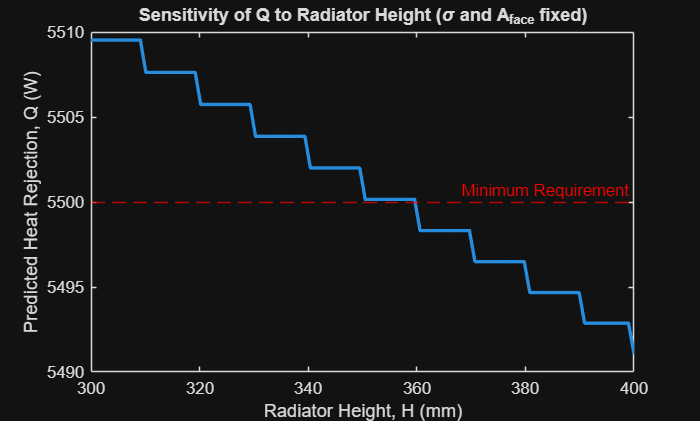

H_range = linspace(0.30, 0.40, 100); % team's given range: 30-40cm

A_face_fixed = A_face_min;% chosen design point
sigma_fixed = sigma_query;% chosen design point

Q_vs_H = zeros(size(H_range));

for m = 1:length(H_range)
    H = H_range(m);
    
    n_tubes = floor(H/tube_pitch); % this is what is changing 
    mdot_tube = mdot_coolant/n_tubes;
    v_water = mdot_tube/(rho_water*A_tube);
    Re_water = (rho_water*v_water*D_h)/mu_water;
    Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.4);
    h_water = (Nu_water*k_water)/D_h;
    
    U = 1/((1/h_air)+(1/h_water));
    
    A_total = sigma_fixed*A_face_fixed*d;
    C_air = rho_air*v_air*cp_air*A_face_fixed;
    C_water = mdot_coolant*cp_water;
    C_min = min(C_air,C_water);
    C_max = max(C_air,C_water);
    C_star = C_min/C_max;
    
    NTU = (U*A_total)/C_min;
    epsilon = 1-exp((NTU^0.22/C_star)*(exp(-C_star*NTU^0.78)-1));
    
    Q_vs_H(m) = epsilon*C_min*(T_coolant_in-T_air_in);
end

plot(H_range*1000, Q_vs_H, 'LineWidth', 2)
xlabel('Radiator Height, H (mm)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(5500, 'r--', 'Minimum Requirement')
title('Sensitivity of Q to Radiator Height (\sigma and A_{face} fixed)')

% this plot shows us that given an area and fin density, varying height
% doesnt have a significant change in heat rejection so calculating heat
% according to fixed height of 350mm for the previous section was fine

## Checking dependency on coolant flow rate

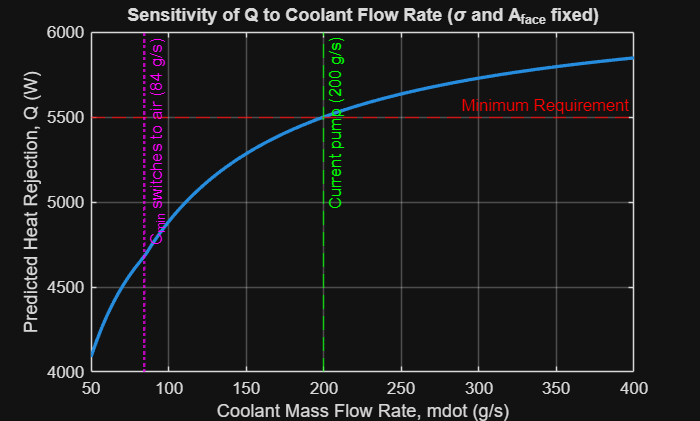

mdot_range_test = linspace(0.05, 0.40, 100);% 50 g/s to 400 g/s

A_face_fixed2 = A_face_min;% chosen design point
sigma_fixed2 = sigma_query;% chosen design point
H_fixed = 0.35;% chosen design point

Q_vs_mdot = zeros(size(mdot_range_test));

n_tubes_fixed = floor(H_fixed/tube_pitch);

for p = 1:length(mdot_range_test)
    mdot_coolant_test = mdot_range_test(p);
    
    % water side h (depends on mdot_coolant_test)
    mdot_tube = mdot_coolant_test/n_tubes_fixed;
    v_water = mdot_tube/(rho_water*A_tube);
    Re_water = (rho_water*v_water*D_h)/mu_water;
    Nu_water = 0.023*(Re_water^0.8)*(Pr_water^0.4);
    h_water_test = (Nu_water*k_water)/D_h;
    
    U_test = 1/((1/h_air)+(1/h_water_test));
    
    A_total_test = sigma_fixed2*A_face_fixed2*d;
    C_air_test = rho_air*v_air*cp_air*A_face_fixed2;
    C_water_test = mdot_coolant_test*cp_water;
    C_min_test = min(C_air_test,C_water_test);
    C_max_test = max(C_air_test,C_water_test);
    C_star_test = C_min_test/C_max_test;
    
    NTU_test = (U_test*A_total_test)/C_min_test;
    epsilon_test = 1-exp((NTU_test^0.22/C_star_test)*(exp(-C_star_test*NTU_test^0.78)-1));
    
    Q_vs_mdot(p) = epsilon_test*C_min_test*(T_coolant_in-T_air_in);
end

figure;
plot(mdot_range_test*1000, Q_vs_mdot, 'LineWidth', 2)
xlabel('Coolant Mass Flow Rate, mdot (g/s)')
ylabel('Predicted Heat Rejection, Q (W)')
yline(5500, 'r--', 'Minimum Requirement')
xline(200, 'g--', 'Current pump (200 g/s)')
xline(84.3, 'm:', 'C_{min} switches to air (84 g/s)', 'LineWidth', 1.5)
title('Sensitivity of Q to Coolant Flow Rate (\sigma and A_{face} fixed)')
grid on

%at lower mdot, cmin = cwater instead of cair so Q drastically increases in
%the start but diminishing returns as later cwater>cair so q = cmin*delta t
%gets a fixed cmin = cair, and delta t only changed by U which isnt
%affected much by water 

## Testing min A_face at diff Fin Densities 

sigma_test_points = [500, 750, 1000, 1250, 1500, 1750, 2000, 2250, 2500, 2750, 3000];

C_q = contourc(sigma_range, A_face_range, Q_predicted, [5500 5500]);
sigma_q = C_q(1, 2:end);
A_face_q = C_q(2, 2:end);
[sigma_q_sorted, idx] = sort(sigma_q);
A_face_q_sorted = A_face_q(idx);

fprintf('%-10s %-15s %-12s\n', 'sigma', 'A_face (m^2)', 'Width (mm)')

sigma      A_face (m^2)    Width (mm)  


for s = sigma_test_points
    A_face_at_s = interp1(sigma_q_sorted, A_face_q_sorted, s);
    W_at_s = A_face_at_s/H*1000;
    fprintf('%-10d %-15.4f %-12.1f\n', s, A_face_at_s, W_at_s)
end

500        NaN             NaN         
750        0.3340          835.0       
1000       0.2617          654.3       
1250       0.2190          547.6       
1500       0.1910          477.5       
1750       0.1713          428.2       
2000       0.1567          391.7       
2250       0.1455          363.8       
2500       0.1368          341.9       
2750       0.1297          324.3       
3000       0.1240          309.9       
